# Aplicación de las ecuaciones diferenciales de orden superior con matemáticas simbólicas en MATLAB

## Definición de parámetros y condiciones iniciales

Sistema masa-resorte con fricción y su ecuación diferencial lineal de orden 2 con coeficientes constantes

$x:$posición

$m:$masa

$f:$constante de fricción viscosa

$k:$ constante elastica de resorte

$F_{ext}:$ fuerza externa


$$\left\{\begin{array}{lll}
 m\ddot{x}+f\dot{x}+kx = F_{ext}(t)&&\\  
 x(0) = 0, \dot{x}=0 && m=0.5kg,\, f=1kg/s^2,\,k=2kg/s
\end{array}\right.$$


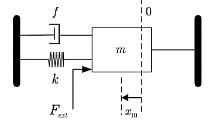

syms x(t)
m = 0.5; f = 1; k = 2;
Dx = diff(x,t,1); D2x = diff(x,t,2);
ci01 = x(0) == 0; ci02 = Dx(0) == 0;

## Solución con una entrada u = 1

u1 = 1;
edo1 = m*D2x + f*Dx + k*x == u1

$$edo1(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)}{2}+\frac{\partial }{\partial t}x\left(t\right)+2\,x\left(t\right)=1$$

sol1 = dsolve(edo1,[ci01 ci02]); simplify(sol1)

$$ans = \frac{1}{2}-\frac{\sqrt{3}\,{\mathrm{e}}^{-t}\,\sin\left(\frac{\pi }{3}+\sqrt{3}\,t\right)}{3}$$

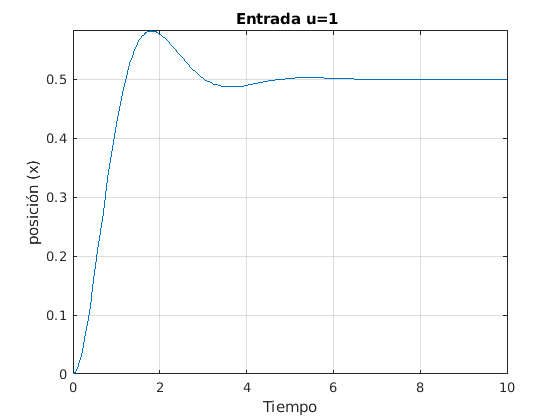

fplot(sol1,[0 10])
grid on
title('Entrada u=1 ')
xlabel('Tiempo')
ylabel('posición (x)')

## Solución con una entrada u = 1 y f = 0

u1 = 1;
edo1 = m*D2x + 0*Dx + k*x == u1

$$edo1(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)}{2}+2\,x\left(t\right)=1$$

sol1 = dsolve(edo1,[ci01 ci02]); simplify(sol1)

$$ans = \frac{1}{2}-\frac{\cos\left(2\,t\right)}{2}$$

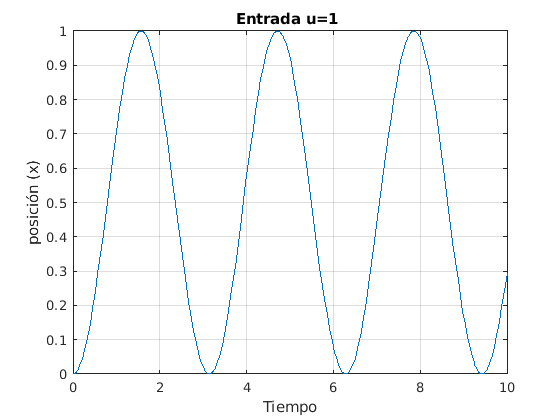

fplot(sol1,[0 10])
grid on
title('Entrada u=1 ')
xlabel('Tiempo')
ylabel('posición (x)')

## Solución con una entrada u = sin(t) y f = 0

Explicación: no hay amortiguamiento.

u2 = sin(t);
edo2 = m*D2x + k*x == u2;
sol2 = dsolve(edo2,[ci01 ci02]);
simplify(sol2)

$$ans = \frac{2\,\sin\left(t\right)}{3}-\frac{\sin\left(2\,t\right)}{3}$$

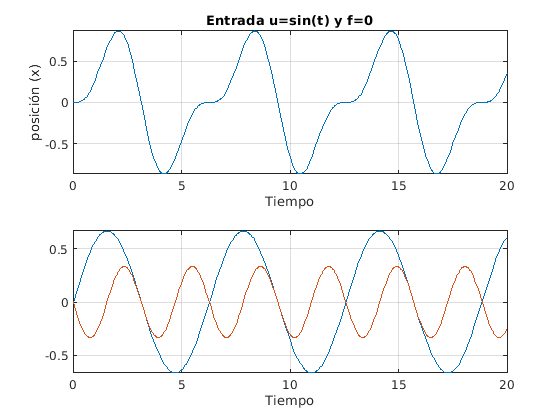

figure
subplot(2,1,1)
fplot(sol2,[0 20])
grid on
title('Entrada u=sin(t) y f=0')
xlabel('Tiempo')
ylabel('posición (x)')
subplot(2,1,2)
fplot(2*sin(t)/3,[0 20])
hold on 
fplot(-sin(2*t)/3,[0 20])
grid on
xlabel('Tiempo')

## Solución con una entrada u = sin(2t) y f = 0

Explicación: resonancia con w = 2 que coincide con la frecuencia natural.

u3 = sin(2*t);
edo3 = m*D2x + k*x == u3;
sol3 = dsolve(edo3,[ci01 ci02]);
simplify(sol3)

$$ans = \frac{\sin\left(2\,t\right)}{4}-\frac{t\,\cos\left(2\,t\right)}{2}$$

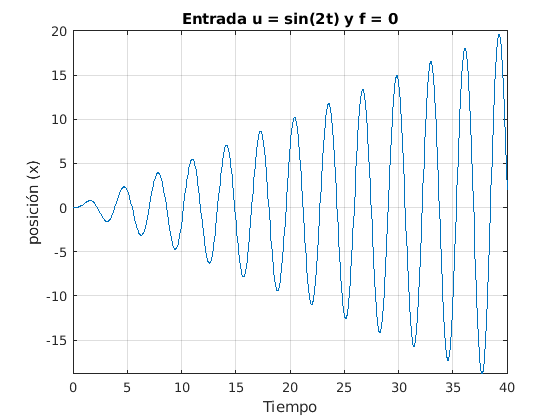

figure
fplot(sol3,[0 40])
grid on
title('Entrada u = sin(2t) y f = 0')
xlabel('Tiempo')
ylabel('posición (x)')

## Solución con cambio de la masa

Explicación: aumento de la inercia.

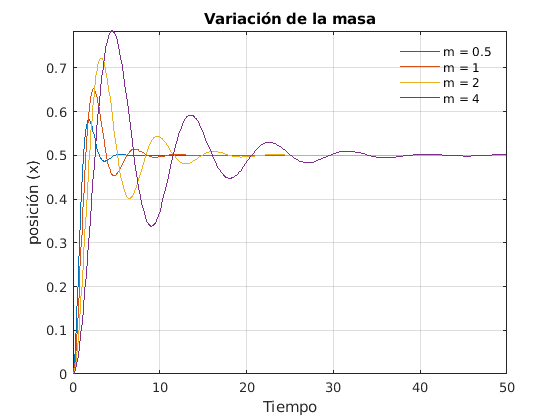

u = 1;
m2 = 0.5; edo4 = m2*D2x + f*Dx + k*x == u; sol41 = dsolve(edo4,[ci01 ci02]);
m2 = 1; edo4 = m2*D2x + f*Dx + k*x == u; sol52 = dsolve(edo4,[ci01 ci02]);
m2 = 2; edo4 = m2*D2x + f*Dx + k*x == u; sol43 = dsolve(edo4,[ci01 ci02]);
m2 = 4; edo4 = m2*D2x + f*Dx + k*x == u; sol44 = dsolve(edo4,[ci01 ci02]);
fplot([sol41 sol52 sol43 sol44],[0 50])
legend({'m = 0.5','m = 1','m = 2','m = 4'},'box','off')
grid on
title('Variación de la masa')
xlabel('Tiempo')
ylabel('posición (x)')

## Solución con cambio de la constante elástica

Explicación: con resortes más rígidos el estiramiento es menor.

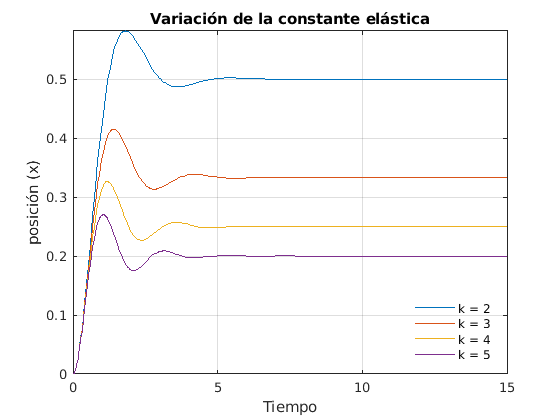

u = 1;
k2 = 2; edo5 = m*D2x + f*Dx + k2*x == u; sol51 = dsolve(edo5,[ci01 ci02]);
k2 = 3; edo5 = m*D2x + f*Dx + k2*x == u; sol52 = dsolve(edo5,[ci01 ci02]);
k2 = 4; edo5 = m*D2x + f*Dx + k2*x == u; sol53 = dsolve(edo5,[ci01 ci02]);
k2 = 5; edo5 = m*D2x + f*Dx + k2*x == u; sol54 = dsolve(edo5,[ci01 ci02]);
fplot([sol51 sol52 sol53 sol54],[0 15])
grid on
legend({'k = 2','k = 3','k = 4','k = 5'}, 'Box','off','Location','best')
title('Variación de la constante elástica')
xlabel('Tiempo')
ylabel('posición (x)')

## Solución con cambio del coeficiente de fricción viscosa

Explicación: al aumentar la fricción el sistema se mueve con más dificultad y hay menos oscilaciones.

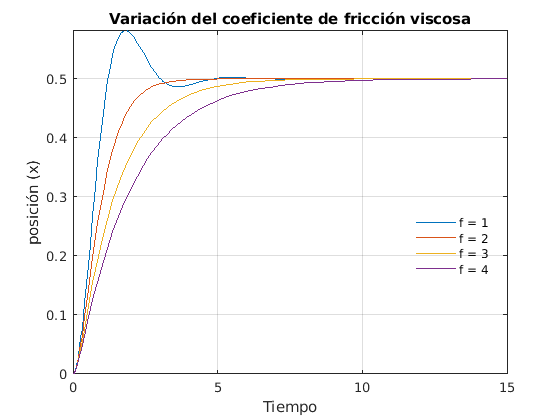

u = 1;
f2 = 1; edo6 = m*D2x + f2*Dx + k*x == u; sol61 = dsolve(edo6,[ci01 ci02]);
f2 = 2; edo6 = m*D2x + f2*Dx + k*x == u; sol62 = dsolve(edo6,[ci01 ci02]);
f2 = 3; edo6 = m*D2x + f2*Dx + k*x == u; sol63 = dsolve(edo6,[ci01 ci02]);
f2 = 4; edo6 = m*D2x + f2*Dx + k*x == u; sol64 = dsolve(edo6,[ci01 ci02]);
fplot([sol61 sol62 sol63 sol64],[0 15])
title('Variación del coeficiente de fricción viscosa')
grid on
xlabel('Tiempo')
ylabel('posición (x)')
legend({'f = 1','f = 2','f = 3','f = 4'}, 'Box','off','Location','best')

**Solución analítica:**

1. Solución general


$$\frac{1}{2}\lambda^2e^{\lambda^2 t} + \lambda e^{\lambda t} + 2 e^{\lambda t} = 0$$


$\frac{1}{2}e^{\lambda^2 t} (\lambda^2+2\lambda + 4) = 0$,   ${2}e^{\lambda^2 t} \neq 0$


$$\lambda^2+2\lambda + 4 = 0$$


Donde las raices son $\lambda = -1\pm i\sqrt{3}$, reemplazando $\lambda$:

$x_1 = C_1e^{(-1+i\sqrt{3})t}$ y $x_2 = C_2e^{(-1-i\sqrt{3})t}$


$$x=x_1+x_2 = C_1e^{(-1+i\sqrt{3})t}+ C_2e^{(-1-i\sqrt{3})t}$$


Ahora, con la identidad de Euler $e^{\alpha +i\beta} = e^{\alpha}\cos(\beta)+ie^{\beta}\sin(\beta)$:


$$x =  C_1[e^{-t}\cos(\sqrt{3}t)+ie^{-t}\sin(\sqrt{3}t)]+C_2[e^{-t}\cos(\sqrt{3}t)-ie^{-t}\sin(\sqrt{3}t)]$$



$$x = (C_1+C_2)(e^{-t}\cos(\sqrt{3}t)) + i(C_1-C2)(e^{-t}\sin(\sqrt{3}t))$$


Renombrando $C_1$ y $C_2$


$$x = C_1(e^{-t}\cos(\sqrt{3}t)) + C_2(e^{-t}\sin(\sqrt{3}t))$$


2. Determinar la solución particular, la cua es de la forma $x_p = a$


$$0+2x_p = u$$



$$2a=u$$



$$a=\frac{u}{2}$$


donde $x+x_p$ es la solución particular:


$$x(t) = C_1\left(e^{-t}\cos(\sqrt{3}t)\right) + C_2(e^{-t}\sin(\sqrt{3}t)) + \frac{u}{2}$$
